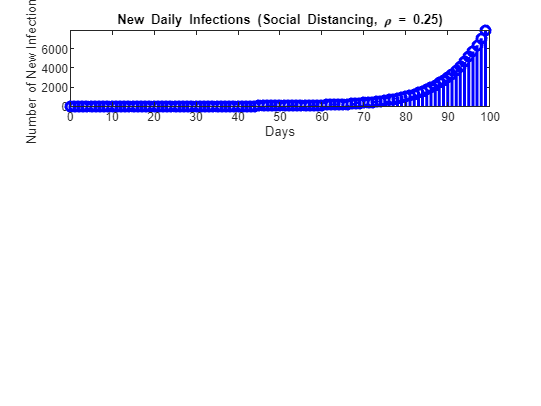

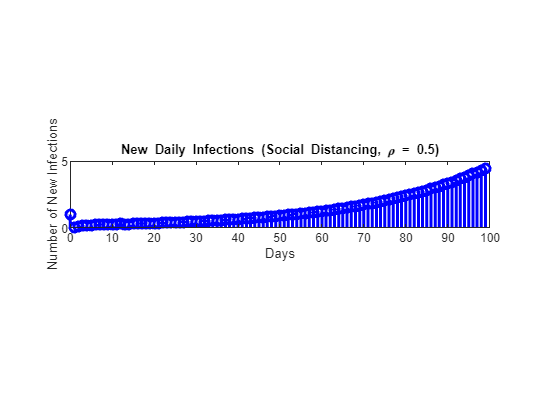

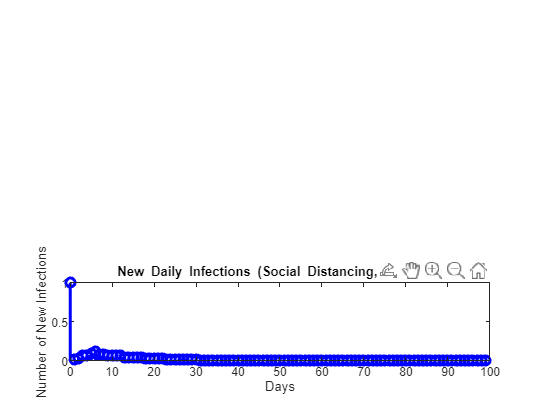

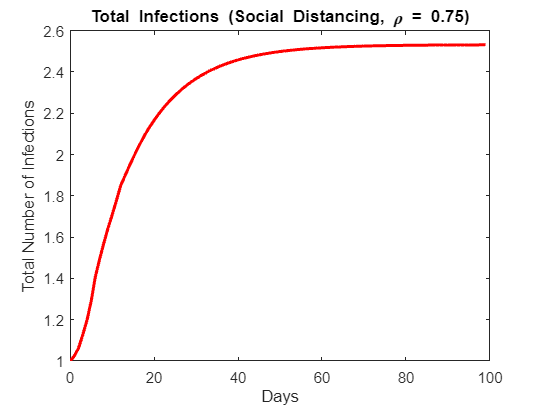

% Parameters
M = 12;
ak = [0.1, 0.15, 0.25, 0.26, 0.34, 0.42, 0.25, 0.2, 0.15, 0.1, 0.1, 0.1];
n_days = 100;
rhos = [0.25, 0.50, 0.75];

% Kronecker delta input
input_signal = [1, zeros(1, n_days - 1)];

% Plotting
figure;
for i = 1:length(rhos)
    rho = rhos(i);
    
    % Transfer function HM(z; rho)
    denominator = [1, -(1 - rho) * ak];
    HM_rho = tf(numerator, denominator);

    % Filtering
    output_signal = filter(1, denominator, input_signal);

    % Integrator filter
    total_infections = cumsum(output_signal);

    % Plot new daily infections
    subplot(length(rhos), 1, i);
    stem(0:n_days-1, output_signal, 'b', 'LineWidth', 2);
    title(['New Daily Infections (Social Distancing, \rho = ' num2str(rho) ')']);
    xlabel('Days');
    ylabel('Number of New Infections');

    % Plot total infections
    figure;
    plot(0:n_days-1, total_infections, 'r', 'LineWidth', 2);
    title(['Total Infections (Social Distancing, \rho = ' num2str(rho) ')']);
    xlabel('Days');
    ylabel('Total Number of Infections');
end